# PCA Visualizations

**Script is used to visualize Principal Component Analysis.**

*Tobi Louw, Dept Process Engineering, Stellenbosch University, 2021*

This script is used to visualize projection by principal component analysis as the optimal rotation of a dataset. An artificial dataset with "N" observations and 3 features is created and plotted in 3D space. The datapoints in "X" follow a normal distribution with mean "mu" and covariance matrix "Sigma". The data is then standardized to give the obeservations "X"

The user may then specify to project the datapoints onto a 2D plane by rotating the plane around the x- or the y-axis, or project the data onto the plane created by the column space of the first two eigenvectors of the covariance matrix. The latter projection corresponds to the first two principal components

clc
clear
clf

% Specify number of observations, mean, and covariance
rng(1)
N = 50;
mu = [1 -1 0];
Sigma = [2.0 -1.5 1.2; ...
         -1.5 2.0 -0.8; ...
         1.2 -0.8 1.5];

% Create data set "X" and standardize to create "Z"
X = mvnrnd(mu, Sigma, N);
Z = (X - mean(X))./std(X);
%figure('Renderer', 'painters', 'OuterPosition', [0 0 1200 300])

### Output

Specify whether to use the eigenvectors of the covariance matrix to specify the projection plane. If not checked the plane will be defined based on the angles specified around the x- and y-axis, respectively.

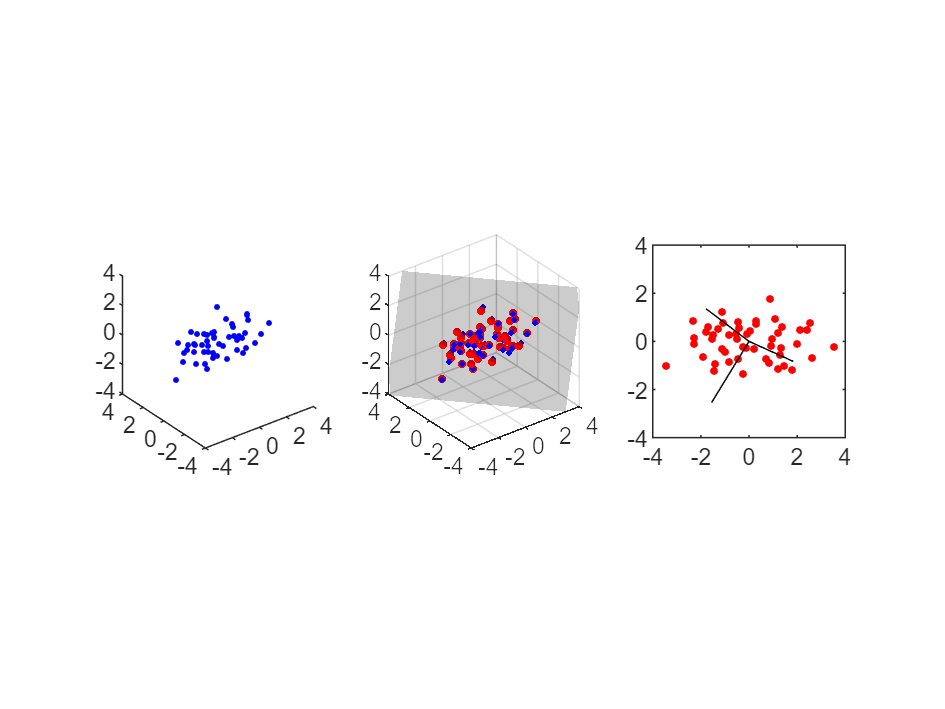

% Use the provided inputs to call the function which will plot and project
% the data onto the specified planeclf
clf
UseEigenVectors = true;
theta.x = -20 * pi/180;
theta.y = -20 * pi/180;
PlotAndProject(Z, UseEigenVectors, theta)

function PlotAndProject(X, UseEigenVectors, theta)

if UseEigenVectors
    % Calculate the first two eigenvectors
    [Q,~] = eigs(X' * X, 2);
else
    % Create a rotatation matrix
    Q =   [1 0 0; 0 cos(theta.x) -sin(theta.x); 0 sin(theta.x) cos(theta.x)]...
         *[cos(theta.y) 0; 0 1; -sin(theta.y) 0];
end

% Create a grid used to visualize the specified plane
xG = meshgrid([-20 20]);
xV = reshape(xG, 4, []);
yV = reshape(xG', 4, []);
zV = xV+yV;

% Create the projected plane in the column space of "Q"
X_out = [xV yV zV]*Q*Q';
x_plane = reshape(X_out(:,1), 2, []);
y_plane = reshape(X_out(:,2), 2, []);
z_plane = reshape(X_out(:,3), 2, []);

% Calculate the projected data points values
t = X*Q;
X_projected = t*Q';

% Create vectors representing the original axes
orig_axes = 3*[1 0 0; 0 0 0; 0 1 0; 0 0 0; 0 0 -1];
t_axes = orig_axes*Q;

% Plotthe original data-points
subplot(1,3,1)
plot3(X(:,1), ...
      X(:,2), ...
      X(:,3),'b.')
hold on
%plot3(4*[-1 1 0 0 0 0 0 0], 4*[0 0 0 -1 1 0 0 0], 4*[0 0 0 0 0 0 -1 1],'k');  % Axes
axis square
axis([-4 4 -4 4 -4 4])
%plot3(4*[0 Q(1,3)], 4*[0 Q(2,3)], 4*[0 Q(3,3)],'r-'); % Normal vector


% Plot the plane, the original data-points, and the data-points projected
% onto the plane
subplot(1,3,2)
s = surf(x_plane, y_plane, z_plane);
s.FaceColor = 'k'; s.FaceAlpha = 0.2; s.LineStyle = 'none';
hold on
plot3([X(:,1) X_projected(:,1)].', ...
      [X(:,2) X_projected(:,2)].', ...
      [X(:,3) X_projected(:,3)].','b.-')
plot3(X_projected(:,1), X_projected(:,2), X_projected(:,3),'r.','MarkerSize',8)
%plot3(4*[-1 1 0 0 0 0 0 0], 4*[0 0 0 -1 1 0 0 0], 4*[0 0 0 0 0 0 -1 1],'k');  % Axes
%plot3(4*[0 Q(1,3)], 4*[0 Q(2,3)], 4*[0 Q(3,3)],'r-'); % Normal vector

axis square
axis([-4 4 -4 4 -4 4])

% Plot the datapoints in 2D, as projected onto the plane
subplot(1,3,3)
plot(t(:,1), t(:,2), 'r.',...
     t_axes(:,1), t_axes(:,2), 'k', ...
     'MarkerSize', 8);
axis square
axis([-4 4 -4 4 -4 4])

end